close all;
clear all;
clc;
J=0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf("s");
sys = K/((J*s+b)*(L*s+R)+K^2);

num_of_evolutions = 10;


pop = generateIntialPopulation(100, sys);

#### **Calculating kp,ki,kd using Ziegra Nichols method..**

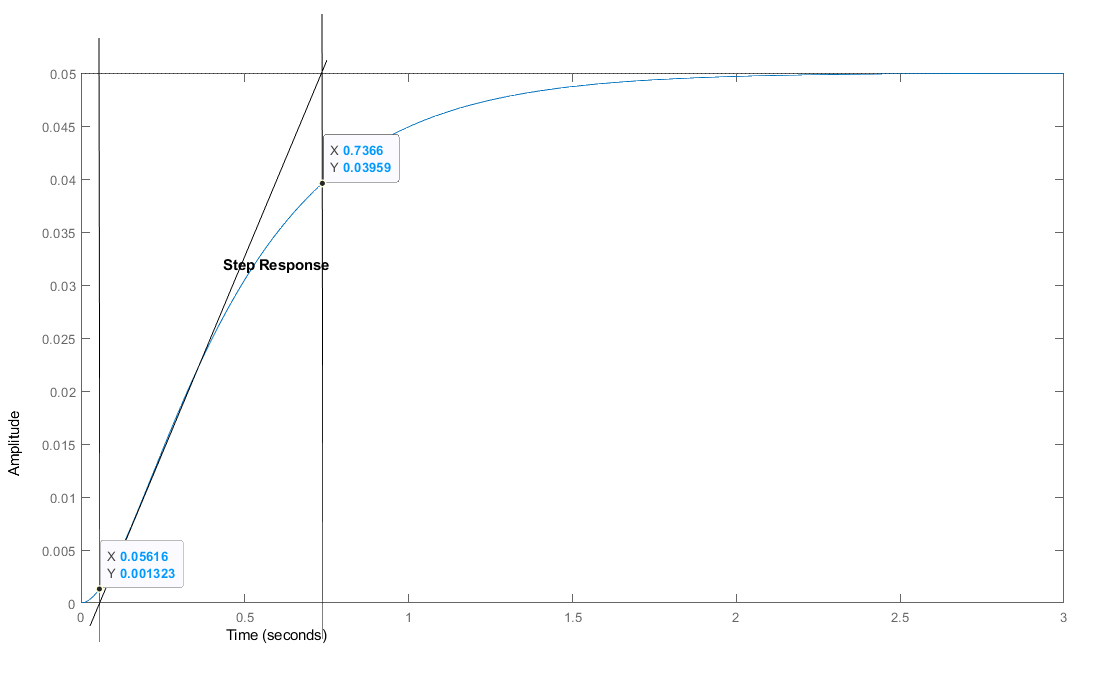

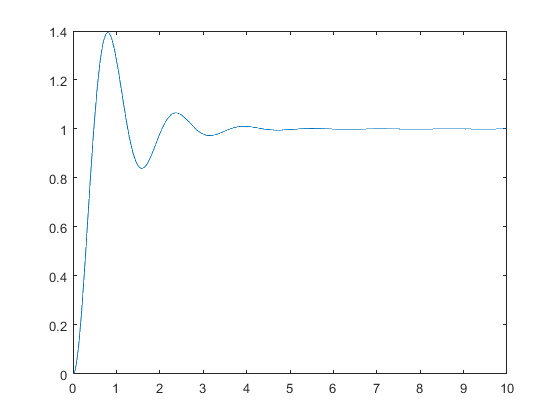

t = 0:0.01:10;
L = 0.05616;
K = 0.05;
T = 0.68049;    % 0.7366-0.05616
kp = round(1.2*T/L);   % 14.5404
ki = round(kp/(2*L));  %129.4550
kd = round(kp*L/2);    %0.4083
y2 = drawFitness(sys, kp,ki,kd, t);
plot(t,y2);

We have to use 8 bits to represent Kp, Ki, Kd values.

## Evolution steps

fprintf("Generation %d \n",0);

Generation 0 


newPop = pop;
max_fitness = min(newPop(4,1,:));
avg_fitness = mean(newPop(4,1,:));

fprintf("cost min : %f, avg : %f \n",max_fitness, avg_fitness);

cost min : 0.024380, avg : 0.145085 



for i=1:num_of_evolutions
    fprintf("Generation %d \n",i);
    newPop = generateNewPopulation(newPop, sys);
    newPop = sort(newPop,3);
    newPop = newPop(:,:,1:100);
    max_fitness = min(newPop(4,1,:));
    avg_fitness = mean(newPop(4,1,:));
    
    fprintf("cost min : %f, avg : %f \n",max_fitness, avg_fitness);
end

Generation 1 


cost min : 0.024380, avg : 0.075872 


Generation 2 


cost min : 0.024380, avg : 0.075294 


Generation 3 


cost min : 0.024380, avg : 0.074998 


Generation 4 


cost min : 0.024380, avg : 0.074555 


Generation 5 


cost min : 0.024380, avg : 0.073939 


Generation 6 


cost min : 0.024380, avg : 0.073476 


Generation 7 


cost min : 0.024380, avg : 0.073189 


Generation 8 


cost min : 0.024380, avg : 0.072714 


Generation 9 


cost min : 0.024380, avg : 0.072030 


Generation 10 


cost min : 0.024380, avg : 0.071596 


## drawing

t = 0:0.01:10;
y0 = step(sys,t);

best_fitness = max(newPop(4,:));
best_fitness_index = find(newPop(4,:) == best_fitness);

y1 = drawFitness(sys, pop(1,best_fitness_index),pop(2,best_fitness_index),pop(3,best_fitness_index), t);

Error using DynamicSystem/step (line 95)
The "step" command operates on a single model when used with output arguments.

Error in drawFitness (line 6)
    y = step(T,t);


% draw response for manual kp,ki,kd values

kp = 14.5404;
ki = 129.4550;
kd = 0.4083;


y2 = drawFitness(sys, kp,ki,kd, t);

figure;
plot(t, y0, 'LineWidth', 1.5);
hold on
plot(t, y1, 'LineWidth', 1.5);
hold off
hold on
plot(t, y2, 'LineWidth', 1.5);
hold off
title('Step Responses');

axis([0 10 0 1.25]);
legend('OpenLoop Response', 'ClosedLoop Response (GA)', 'ClosedLoop Response (Manual)');
grid on;